# Create DQN Agent Using Initialization Options

Create an environment with a discrete action space, and obtain its observation and action specifications. For this example, load the environment used in the example [Create Agent Using Deep Network Designer and Train Using Image Observations](docid:rl_ug#mw_c86f43ba-61a0-4a4c-9820-8b78c2559268). This environment has two observations: a 50-by-50 grayscale image and a scalar (the angular velocity of the pendulum). The action is a scalar with five possible elements (a torque of either -`2`, -`1`, `0`, `1`, or `2` Nm applied to a swinging pole).

% load predefined environment
env = rlPredefinedEnv("SimplePendulumWithImage-Discrete");

% obtain observation and action specifications
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

Create an agent initialization option object, specifying that each hidden fully connected layer in the network must have `128` neurons (instead of the default number, `256`).

initOpts = rlAgentInitializationOptions('NumHiddenUnit',128);

The agent creation function initializes the actor and critic networks randomly. You can ensure reproducibility by fixing the seed of the random generator. To do so, uncomment the following line.

% rng(0)

Create a policy gradient agent from the environment observation and action specifications.

agent = rlDQNAgent(obsInfo,actInfo,initOpts);

Reduce the critic learning rate to 1e-3.

critic = getCritic(agent);
critic.Options.LearnRate = 1e-3;
agent  = setCritic(agent,critic);

Extract the deep neural network from both the critic.

criticNet = getModel(getCritic(agent));

The default DQN agent uses a multi-output Q-value critic approximator. A multi-output approximator has observations as inputs and state-action values as outputs. Each output element represents the expected cumulative long-term reward for taking the corresponding discrete action from the state indicated by the observation inputs. 

Display the layers of the critic network, and verify that each hidden fully connected layer has 128 neurons

criticNet.Layers

ans =   12×1 Layer array with layers:

     1   'concat'               Concatenation       Concatenation of 2 inputs along dimension 3
     2   'relu_body'            ReLU                ReLU
     3   'fc_body'              Fully Connected     128 fully connected layer
     4   'body_output'          ReLU                ReLU
     5   'input_1'              Image Input         50×50×1 images
     6   'conv_1'               Convolution         64 3×3×1 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'relu_input_1'         ReLU                ReLU
     8   'fc_1'                 Fully Connected     128 fully connected layer
     9   'input_2'              Image Input         1×1×1 images
    10   'fc_2'                 Fully Connected     128 fully connected layer
    11   'output'               Fully Connected     5 fully connected layer
    12   'RepresentationLoss'   Regression Output   mean-

 Plot the critic network

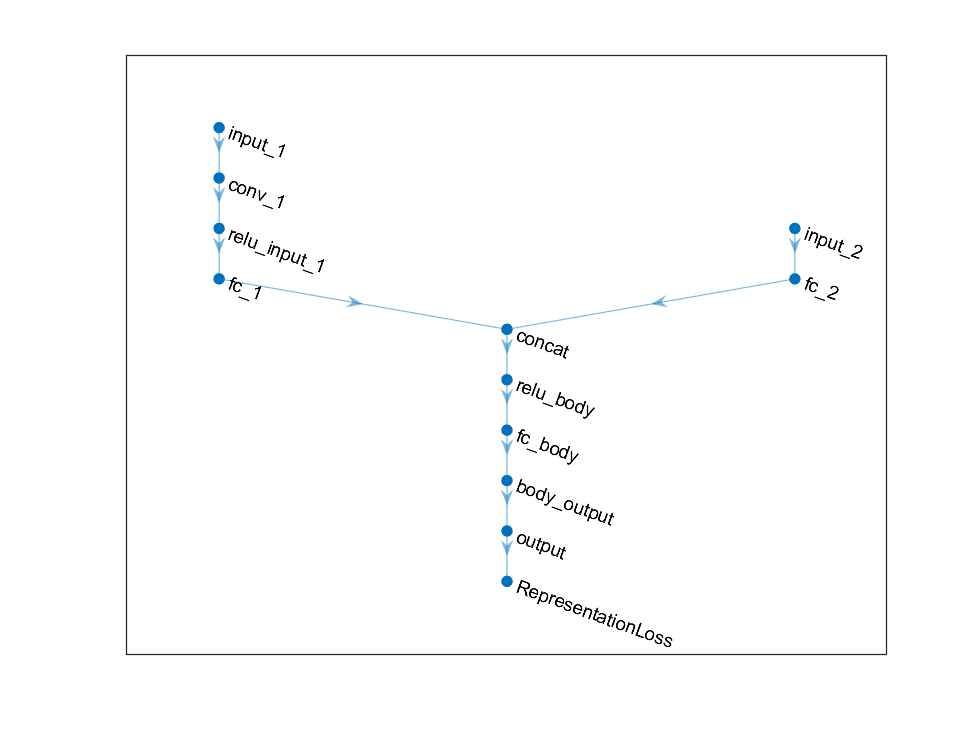

plot(criticNet)

To check your agent, use `getAction` to return the action from a random observation.

getAction(agent,{rand(obsInfo(1).Dimension),rand(obsInfo(2).Dimension)})

ans = 1

You can now test and train the agent within the environment.

*Copyright 2020 The MathWorks, Inc.*